# Pre-Processing

## Prepare the Environment

clc;
clearvars;
close all;

## Migration Dataset Cleaning

% Migration table
migrationT = readtable('./Datasets/migration-flows.csv', 'Delimiter', ',', 'TextType', 'string', 'VariableNamingRule', 'preserve', 'Format', 'auto');

% Change column order
migrationT = movevars(migrationT, "Year", "After", "Country");

% Assinging types to variables
migrationT.Properties.VariableUnits(1, 1:2) = ["categorical", "int"];
migrationT.Properties.VariableUnits(1, 3:length(migrationT.Properties.VariableNames)) = "int";

% Removing lines having no info about migration flows
migrationT(all(ismissing(migrationT(:, 3:length(migrationT.Properties.VariableNames))), 2), :) = [];

% Replacing Nan values with 0
idx = ismissing(migrationT(:, 3:length(migrationT.Properties.VariableNames)));
migrationT{:, 3:length(migrationT.Properties.VariableNames)}(idx) = 0;

% Sorting rows by Country name and Year
migrationT = sortrows(migrationT, [1, 2]);

head(migrationT)

       Country       Year    Emigrants from Afghanistan    Immigrants to Afghanistan    Emigrants from Albania    Immigrants to Albania    Emigrants from Algeria    Immigrants to Algeria    Emigrants from American Samoa    Immigrants to American Samoa    Emigrants from Andorra    Immigrants to Andorra    Emigrants from Angola    Immigrants to Angola    Emigrants from Anguilla    Immigrants to Anguilla    Emigrants from Antigua and Barbuda    Immigrants to Antigua and Barbuda    Emigrants from Argentina    Immigrants to Argentina    Emigrants from Armenia    Immigrants to Armenia    Emigrants from Aruba

summary(migrationT)

Variables:

    Country: 1659×1 string

        Properties:
            Units:  categorical
    Year: 1659×1 double

        Properties:
            Units:  int
        Values:

            Min         1990  
            Median      2005  
            Max         2020  

    Emigrants from Afghanistan: 1659×1 double

        Properties:
            Units:  int
        Values:

            Min       -7.6796e+06
            Median              0
            Max        3.9803e+06

    Immigrants to Afghanistan: 1659×1 double

        Properties:
            Units:  int
        Values:

            Min       -2.6837e+05
            Median              0
            Max        3.3943e+05

    Emigrants from Albania: 1659×1 double

        Properties:
            Units:  int
        Values:

            Min       -1.2505e+06
            Median              0
            Max        4.8619e+05

    Imm


clearvars("idx")

## GDP per capita Dataset Cleaning

gdpT = readtable('./Datasets/gdp_per_capita.csv', 'Delimiter', ',', 'TextType', 'string', 'VariableNamingRule', 'preserve', 'Format', 'auto');

% Assinging types to variables
gdpT.Properties.VariableUnits = ["categorical", "categorical", "int", "double", "double", "categorical"];

% Removing rows outside the useful time interval
idx = ismember(gdpT.Year, unique(migrationT.Year));
gdpT(~idx, :) = [];

% Removing regions
idx = gdpT.Code=="";
gdpT(idx, :) = [];

% Sorting rows by Country name and Year
gdpT = sortrows(gdpT, [1, 3]);

% Removing lines having no info about gdp
gdpT(any(ismissing(gdpT(:, 4)), 2), :) = [];

% Filling continent values
gdpT(gdpT.Country=="World", "Continent") = {"Earth"};
countries = unique(gdpT.Country)';

for country = countries   
    missingValues = table2array(gdpT(gdpT.Country==country, "Continent"))=="";
    
    if any(missingValues)
        continentValues = table2array(gdpT(gdpT.Country==country, "Continent"));
        continent = unique(continentValues(~missingValues));
        if ~(continent == "")
            continentValues(missingValues) = continent;
            gdpT(gdpT.Country==country, "Continent") = cellstr(continentValues);
        end
    end
    
end

head(gdpT)

       Country       Code     Year    GDP_per_capita    Population    Continent
    _____________    _____    ____    ______________    __________    _________

    "Afghanistan"    "AFG"    1990          1138        1.4965e+07    "Asia"   
    "Afghanistan"    "AFG"    1995        1197.4        1.4965e+07    "Asia"   
    "Afghanistan"    "AFG"    2000        1256.7        1.8668e+07    "Asia"   
    "Afghanistan"    "AFG"    2005        1352.3        2.4405e+07    "Asia"   
    "Afghanistan"    "AFG"    2010        2026.2        2.8284e+07    "Asia"   
    "Afghanistan"    "AFG"    2015        2108.7        3.3832e+07    "Asia"   
    "Afghanistan"    "AFG"    2020        1968.3        3.9069e+07    "Asia"   
    "Albania"        "ALB"    1990        4827.1         3.278e+06    "Euro

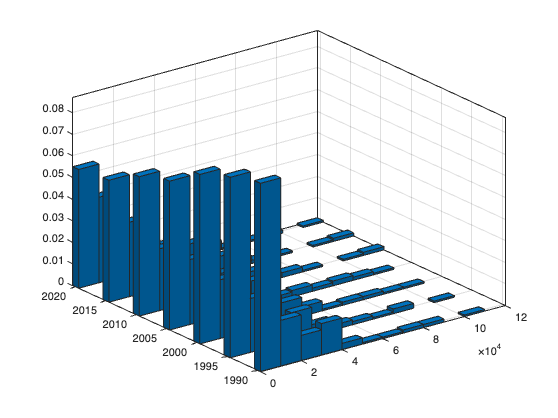

figure;
histogram2(gdpT.GDP_per_capita, gdpT.Year, "Normalization", "probability")

summary(gdpT)

Variables:

    Country: 1365×1 string

        Properties:
            Units:  categorical
    Code: 1365×1 string

        Properties:
            Units:  categorical
    Year: 1365×1 double

        Properties:
            Units:  int
        Values:

            Min         1990  
            Median      2005  
            Max         2020  

    GDP_per_capita: 1365×1 double

        Properties:
            Units:  double
        Values:

            Min           459.87
            Median         10152
            Max       1.1685e+05

    Population: 1365×1 double

        Properties:
            Units:  double
        Values:

            Min             8821
            Median    6.0019e+06
            Max        7.887e+09

    Continent: 1365×1 string

        Properties:
            Units:  categorical



clearvars("continentValues", "continent", "countries", "country", "missingValues", "idx")

## Gini Coefficient Dataset Cleaning

giniT = readtable('./Datasets/gini_coeff.csv', 'Delimiter', ',', 'TextType', 'string', 'VariableNamingRule', 'preserve', 'Format', 'auto');

% Assinging types to variables
giniT.Properties.VariableUnits = ["categorical", "categorical", "int", "double"];

% Removing rows outside the useful time interval
idx = ismember(giniT.Year, unique(migrationT.Year));
giniT(~idx, :) = [];

% Sorting rows by Country name and Year
giniT = sortrows(giniT, [1, 3]);

% Removing lines having no info about Gini coefficient
giniT(any(ismissing(giniT(:, 4)), 2), :) = [];

head(giniT)

     Country     Code     Year    Gini_coeff
    _________    _____    ____    __________

    "Albania"    "ALB"    1990     0.22282  
    "Albania"    "ALB"    1995     0.26222  
    "Albania"    "ALB"    2000     0.30163  
    "Albania"    "ALB"    2005     0.30596  
    "Albania"    "ALB"    2010     0.29473  
    "Albania"    "ALB"    2015     0.32754  
    "Albania"    "ALB"    2020      0.2942  
    "Algeria"    "DZA"    1990     0.36778  



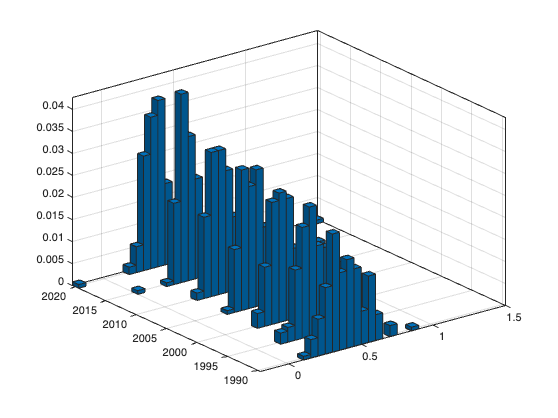

figure;
histogram2(giniT.Gini_coeff, giniT.Year, "Normalization", "probability")

summary(giniT)

Variables:

    Country: 1192×1 string

        Properties:
            Units:  categorical
    Code: 1192×1 string

        Properties:
            Units:  categorical
    Year: 1192×1 double

        Properties:
            Units:  int
        Values:

            Min         1990  
            Median      2005  
            Max         2020  

    Gini_coeff: 1192×1 double

        Properties:
            Units:  double
        Values:

            Min       -0.1997 
            Median    0.37872 
            Max        1.4758 




clearvars("idx")

## Human-Development Index Dataset Cleaning

humanDvpmT = readtable('./Datasets/human_Dvpm_Index.csv', 'Delimiter', ',', 'TextType', 'string', 'VariableNamingRule', 'preserve', 'Format', 'auto');

% Assinging types to variables
humanDvpmT.Properties.VariableUnits = ["categorical", "categorical", "int", "double"];

% Removing rows outside the useful time interval
idx = ismember(humanDvpmT.Year, unique(migrationT.Year));
humanDvpmT(~idx, :) = [];

% Sorting rows by Country name and Year
humanDvpmT = sortrows(humanDvpmT, [1, 3]);

% Removing lines having no info about Gini coefficient
humanDvpmT(any(ismissing(humanDvpmT(:, 4)), 2), :) = [];

head(humanDvpmT)

       Country       Code     Year    Human_Dvpm_Index
    _____________    _____    ____    ________________

    "Afghanistan"    "AFG"    1990         0.284      
    "Afghanistan"    "AFG"    1995         0.318      
    "Afghanistan"    "AFG"    2000          0.34      
    "Afghanistan"    "AFG"    2005         0.402      
    "Afghanistan"    "AFG"    2010         0.449      
    "Afghanistan"    "AFG"    2015         0.479      
    "Afghanistan"    "AFG"    2020         0.488      
    "Albania"        "ALB"    1990         0.649      



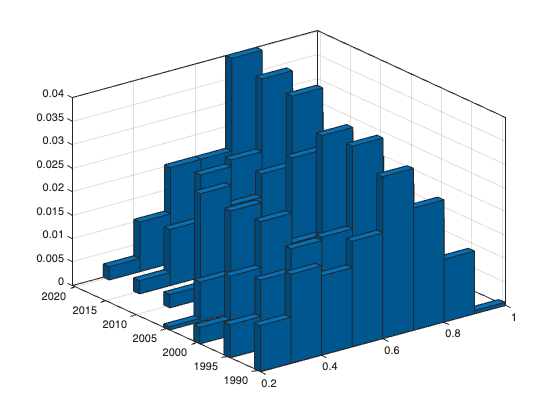

figure;
histogram2(humanDvpmT.Human_Dvpm_Index, humanDvpmT.Year, "Normalization", "probability")

summary(humanDvpmT)

Variables:

    Country: 1421×1 string

        Properties:
            Units:  categorical
    Code: 1421×1 string

        Properties:
            Units:  categorical
    Year: 1421×1 double

        Properties:
            Units:  int
        Values:

            Min         1990  
            Median      2005  
            Max         2020  

    Human_Dvpm_Index: 1421×1 double

        Properties:
            Units:  double
        Values:

            Min        0.2002 
            Median      0.675 
            Max         0.963 




clearvars("idx")

## Unemployment Rate Dataset Cleaning

unemploymentT = readtable('./Datasets/unemployment_rate.csv', 'Delimiter', ',', 'TextType', 'string', 'VariableNamingRule', 'preserve', 'Format', 'auto');

% Assinging types to variables
unemploymentT.Properties.VariableUnits = ["categorical", "categorical", "int", "double"];

% Removing rows outside the useful time interval
idx = ismember(unemploymentT.Year, unique(migrationT.Year));
unemploymentT(~idx, :) = [];

% Sorting rows by Country name and Year
unemploymentT = sortrows(unemploymentT, [1, 3]);

% Removing lines having no info about Gini coefficient
unemploymentT(any(ismissing(unemploymentT(:, 4)), 2), :) = [];

head(unemploymentT)

       Country       Code     Year    Unemployment_Rate
    _____________    _____    ____    _________________

    "Afghanistan"    "AFG"    1990          7.944      
    "Afghanistan"    "AFG"    1995          7.942      
    "Afghanistan"    "AFG"    2000          7.942      
    "Afghanistan"    "AFG"    2005          7.925      
    "Afghanistan"    "AFG"    2010          7.921      
    "Afghanistan"    "AFG"    2015          9.002      
    "Afghanistan"    "AFG"    2020          11.71      
    "Albania"        "ALB"    1990         7.2149      



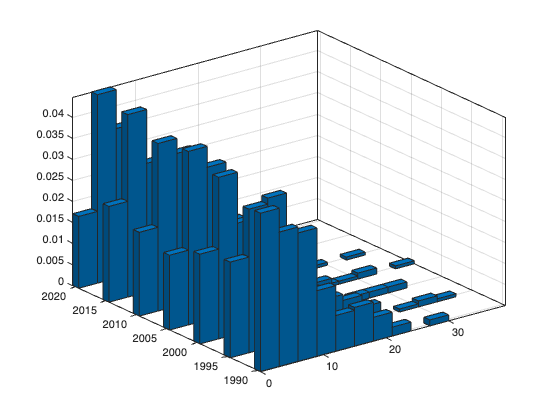

figure;
histogram2(unemploymentT.Unemployment_Rate, unemploymentT.Year, "Normalization", "probability")

summary(unemploymentT)

Variables:

    Country: 1407×1 string

        Properties:
            Units:  categorical
    Code: 1407×1 string

        Properties:
            Units:  categorical
    Year: 1407×1 double

        Properties:
            Units:  int
        Values:

            Min         1990  
            Median      2005  
            Max         2020  

    Unemployment_Rate: 1407×1 double

        Properties:
            Units:  double
        Values:

            Min          0.14 
            Median     6.6877 
            Max         37.32 




clearvars("idx")

## Distance Dataset Cleaning

distanceT = readtable('./Datasets/country_dist.xls', 'TextType', 'string', 'VariableNamingRule', 'preserve');

% Remove useless columns
distanceT(:, end-3:end-1) = [];

% Renaming Variables
distanceT.Properties.VariableNames(1) = "Code_Origin";
distanceT.Properties.VariableNames(2) = "Code_Destination";
distanceT.Properties.VariableNames(end) = "Distance";

% Remove useless rows
idx = distanceT.Code_Origin==distanceT.Code_Destination;
distanceT(idx, :) = [];

% Update variable names capitalizing first letter
len = length(distanceT.Properties.VariableNames);
for i = 1:len
    variable = distanceT.Properties.VariableNames{i};    
    variable(1) = upper(variable(1));
    distanceT.Properties.VariableNames{i} = variable;
end

% Overall language distace
officialLang = distanceT.Comlang_off;
ethnoLang = distanceT.Comlang_ethno;
language = 0.8 * officialLang + 0.2 * ethnoLang;

% Overall colony distance
colonial_link = distanceT.Colony;
colonizer_after45 = distanceT.Comcol;
current_colony = distanceT.Curcol;
col_relation_after45 = distanceT.Col45;
colony = 0.6 * current_colony + 0.2 * colonizer_after45 + 0.15 * col_relation_after45 + 0.05 * colonial_link;

% Remove redundant columns
distanceT(:, 4:9) = [];

% Add summary distance variables
distanceT = [distanceT, num2cell(language), num2cell(colony)];

% Rename summary distance variables
distanceT.Properties.VariableNames(end-1) = "Language";
distanceT.Properties.VariableNames(end) = "Colony";

% Update variable types
distanceT.Properties.VariableUnits = ["categorical", "categorical", "double", "double", "double", "double", "double"];

head(distanceT)

    Code_Origin    Code_Destination    Contig    Smctry    Distance    Language    Colony
    ___________    ________________    ______    ______    ________    ________    ______

       "ABW"            "AFG"            0         0         13166         0          0  
       "ABW"            "AGO"            0         0        9584.2         0          0  
       "ABW"            "AIA"            0         0        976.89       0.2          0  
       "ABW"            "ALB"            0         0        9091.5         0          0  
       "ABW"            "AND"            0         0        7570.1       0.8          0  
       "ABW"            "ANT"            0         1        142.86         1        0.2  
       "ABW"            "ARE"            

summary(distanceT)

Variables:

    Code_Origin: 49952×1 string

        Properties:
            Units:  categorical
    Code_Destination: 49952×1 string

        Properties:
            Units:  categorical
    Contig: 49952×1 double

        Properties:
            Units:  double
        Values:

            Min          0    
            Median       0    
            Max          1    

    Smctry: 49952×1 double

        Properties:
            Units:  double
        Values:

            Min          0    
            Median       0    
            Max          1    

    Distance: 49952×1 double

        Properties:
            Units:  double
        Values:

            Min             33.257  
            Median          8017.7  
            Max             19780   
            NumMissing      2210    

    Language: 49952×1 double

        Properties:
            Units:  double
        Values:

  


clearvars("idx", "len", "i", "variable", "officialLang", "ethnoLang", "colonial_link", ...
    "colonizer_after45", "current_colony", "col_relation_after45", "language", "colony")

## Integrate Code column in Migration Table

upd_distanceT = migrationT;
country_codeT = [unique(gdpT(:, "Country"), "stable"), unique(gdpT(:, "Code"), "stable")];

% Add Code column
upd_distanceT = innerjoin(upd_distanceT, country_codeT, "Keys", "Country");
upd_distanceT.Properties.VariableNames(end) = "Code";
migrationT = movevars(upd_distanceT, "Code", "After", "Country");

clearvars("upd_distanceT", "country_codeT")

## Integrate Country column in Distance Table

upd_distanceT = distanceT;
country_codeT = [unique(migrationT(:, "Country"), "stable"), unique(migrationT(:, "Code"), "stable")];

% Add origin country column
upd_distanceT = innerjoin(upd_distanceT, country_codeT, "LeftKeys", "Code_Origin", "RightKeys", "Code")

upd_distanceT = 41255×8 table
    Code_Origin    Code_Destination    Contig    Smctry    Distance    Language    Colony    Country
    ___________    ________________    ______    ______    ________    ________    ______    _______

       "ABW"            "AFG"            0         0         13166         0          0      "Aruba"
       "ABW"            "AGO"            0         0        9584.2         0          0      "Aruba"
       "ABW"            "AIA"            0         0        976.89       0.2          0      "Aruba"
       "ABW"            "ALB"            0         0        9091.5         0          0      "Aruba"
       "ABW"            "AND"            0         0        7570.1       0.8          0    

upd_distanceT.Properties.VariableNames(end) = "Country_Origin";
upd_distanceT = movevars(upd_distanceT, "Country_Origin", "Before", "Code_Origin");

% Add destination country column
upd_distanceT = innerjoin(upd_distanceT, country_codeT, "LeftKeys", "Code_Destination", "RightKeys", "Code")

upd_distanceT = 34040×9 table
        Country_Origin        Code_Origin    Code_Destination    Contig    Smctry    Distance    Language    Colony    Country
    ______________________    ___________    ________________    ______    ______    ________    ________    ______    _______

    "Afghanistan"                "AFG"            "ABW"            0         0         13166         0         0       "Aruba"
    "Angola"                     "AGO"            "ABW"            0         0        9584.2         0         0       "Aruba"
    "Albania"                    "ALB"            "ABW"            0         0        9091.5         0         0       "Aruba"
    "United Arab Emirates"  

upd_distanceT.Properties.VariableNames(end) = "Country_Destination";
upd_distanceT = movevars(upd_distanceT, "Country_Destination", "Before", "Code_Origin");

% Sorting rows by Country name
distanceT = sortrows(upd_distanceT, "Country_Origin")

distanceT = 34040×9 table
    Country_Origin     Country_Destination      Code_Origin    Code_Destination    Contig    Smctry    Distance    Language    Colony
    ______________    ______________________    ___________    ________________    ______    ______    ________    ________    ______

    "Afghanistan"     "Aruba"                      "AFG"            "ABW"            0         0         13166        0          0   
    "Afghanistan"     "Angola"                     "AFG"            "AGO"            0         0        7563.8        0          0   
    "Afghanistan"     "Albania"                    "AFG"            "ALB"            0         0        4243.1        0          0 


clearvars("country_codeT", "upd_distanceT")

## Information by country

% Check what info abou migrationT countries is not retrievable
migrationCountry = unique(migrationT.Country);
gdpCountry = unique(gdpT.Country);
humanDvpmCountry = unique(humanDvpmT.Country);
giniCountry = unique(giniT.Country);
unemploymentCountry= unique(unemploymentT.Country);
distanceCountry= unique(distanceT.Country_Origin);

% Display which info is not available per country
disp("Countries having no GDP info:")

Countries having no GDP info:


noGDPCountry = setdiff(migrationCountry, gdpCountry)


noGDPCountry = 

  0×1 empty string array




disp("Countries having no human development index info:")

Countries having no human development index info:


noHumanDvpmCountry = setdiff(migrationCountry, humanDvpmCountry)

noHumanDvpmCountry = 9×1 string array
    "Aruba"
    "Bermuda"
    "Cayman Islands"
    "Curacao"
    "Macao"
    "Puerto Rico"
    "Sint Maarten (Dutch part)"
    "Somalia"
    "Turks and Caicos Islands"



disp("Countries having no poverty info:")

Countries having no poverty info:


noGiniCountry = setdiff(migrationCountry, giniCountry)

noGiniCountry = 37×1 string array
    "Afghanistan"
    "Antigua and Barbuda"
    "Argentina"
    "Aruba"
    "Bahamas"
    "Bahrain"
    "Barbados"
    "Bermuda"
    "Brunei"
    "Cambodia"
    "Cayman Islands"
    "Curacao"
    "Dominica"
    "Equatorial Guinea"
    "Grenada"
    "Hong Kong"
    "Kuwait"
    "Lebanon"
    "Libya"
    "Macao"
    "Marshall Islands"
    "Nauru"
    "New Zealand"
    "Oman"
    "Palau"
    "Puerto Rico"
    "Qatar"
    "Saint Kitts and Nevis"
    "Saint Vincent and the Grenadines"
    "San Marino"



disp("Countries having no unemployment rate info:")

Countries having no unemployment rate info:


noUnemploymentCountry = setdiff(migrationCountry, unemploymentCountry)

noUnemploymentCountry = 18×1 string array
    "Antigua and Barbuda"
    "Aruba"
    "Bermuda"
    "Cayman Islands"
    "Curacao"
    "Dominica"
    "Grenada"
    "Kiribati"
    "Marshall Islands"
    "Micronesia (country)"
    "Nauru"
    "Palau"
    "Saint Kitts and Nevis"
    "San Marino"
    "Seychelles"
    "Sint Maarten (Dutch part)"
    "Turks and Caicos Islands"
    "Tuvalu"



disp("Countries having no distance info:")

Countries having no distance info:


nodistanceCountry = setdiff(migrationCountry, distanceCountry)

nodistanceCountry = 7×1 string array
    "Curacao"
    "Democratic Republic of Congo"
    "Montenegro"
    "Palestine"
    "Romania"
    "Serbia"
    "Sint Maarten (Dutch part)"



% Migration countries defined by all the economic indicators
commCountries = intersect(migrationCountry, gdpCountry);
commCountries = intersect(commCountries, humanDvpmCountry);
commCountries = intersect(commCountries, giniCountry);
commCountries = intersect(commCountries, unemploymentCountry);
commCountries = intersect(commCountries, distanceCountry);
disp('Set of countries having a match in all datasets:')

Set of countries having a match in all datasets:


commCountries   % Countries in common

commCountries = 146×1 string array
    "Albania"
    "Algeria"
    "Angola"
    "Armenia"
    "Australia"
    "Austria"
    "Azerbaijan"
    "Bangladesh"
    "Belarus"
    "Belgium"
    "Belize"
    "Benin"
    "Bhutan"
    "Bolivia"
    "Bosnia and Herzegovina"
    "Botswana"
    "Brazil"
    "Bulgaria"
    "Burkina Faso"
    "Burundi"
    "Cameroon"
    "Canada"
    "Cape Verde"
    "Central African Republic"
    "Chad"
    "Chile"
    "China"
    "Colombia"
    "Comoros"
    "Congo"



clearvars("migrationCountry", "gdpCountry", "humanDvpmCountry", "giniCountry", "unemploymentCountry", ...
    "noGDPCountry", "noHumanDvpmCountry", "noGiniCountry", "noUnemploymentCountry", "nodistanceCountry", ...
    "distanceCountry")

## Update tables rows

% Removing unnecessary country rows 
idx = ismember(migrationT.Country, commCountries);
non_commCountries = setdiff(unique(migrationT.Country), commCountries);
migrationT(~idx, :) = [];
for country = non_commCountries
    emigrant_col = "Emigrants from " + country;
    immigrant_col = "Immigrants to " + country;
    migrationT(:, [emigrant_col, immigrant_col]) = [];
end

% Removing unnecessary country rows 
idx = ismember(gdpT.Country, commCountries);
gdpT(~idx, :) = [];

idx = ismember(giniT.Country, commCountries);
giniT(~idx, :) = [];

idx = ismember(humanDvpmT.Country, commCountries);
humanDvpmT(~idx, :) = [];

idx = ismember(unemploymentT.Country, commCountries);
unemploymentT(~idx, :) = [];

idx = ismember(distanceT.Country_Origin, commCountries);
distanceT(~idx, :) = [];
idx = ismember(distanceT.Country_Destination, commCountries);
distanceT(~idx, :) = [];

clearvars("idx", "country", "emigrant_col", "immigrant_col", "non_commCountries")

## Integrate Total Immigrants and Emigrants column in Migration table

country = unique(migrationT.Country);
years = unique(migrationT.Year);
numCountry = length(country);
numYear = length(years);
Total_Emigrants = zeros(size(migrationT, 1), 1);
Total_Immigrants = zeros(size(migrationT, 1), 1);

for i = 1:numCountry   
    idx = migrationT.Country == country(i);
    startIdx = (i - 1) * numYear + 1;
    endIdx = i * numYear;

    for j = 1:numCountry
    
        if country(i) ~= country(j)
            emigrant_col = "Emigrants from " + country(j);
            immigrant_col = "Immigrants to " + country(j);            
            Total_Emigrants(startIdx:endIdx, :) = Total_Emigrants(startIdx:endIdx, :) + migrationT{idx, immigrant_col};
            Total_Immigrants(startIdx:endIdx, :) = Total_Immigrants(startIdx:endIdx, :) + migrationT{idx, emigrant_col};
        end

    end
       
end
migrationT = [migrationT, array2table(Total_Emigrants), array2table(Total_Immigrants)];

head(migrationT)

     Country     Code     Year    Emigrants from Albania    Immigrants to Albania    Emigrants from Algeria    Immigrants to Algeria    Emigrants from American Samoa    Immigrants to American Samoa    Emigrants from Andorra    Immigrants to Andorra    Emigrants from Angola    Immigrants to Angola    Emigrants from Anguilla    Immigrants to Anguilla    Emigrants from Armenia    Immigrants to Armenia    Emigrants from Australia    Immigrants to Australia    Emigrants from Austria    Immigrants to Austria    Emigrants from Azerbaijan    Immigrants to Azerbaijan    Emigrants from Bangladesh


clearvars("country", "years", "numCountry", "numYear", "Total_Immigrants", "Total_Emigrants", ...
    "i", "idx", "startIdx", "endIdx", "j", "emigrant_col", "immigrant_col")

## Display Migration flow distribution

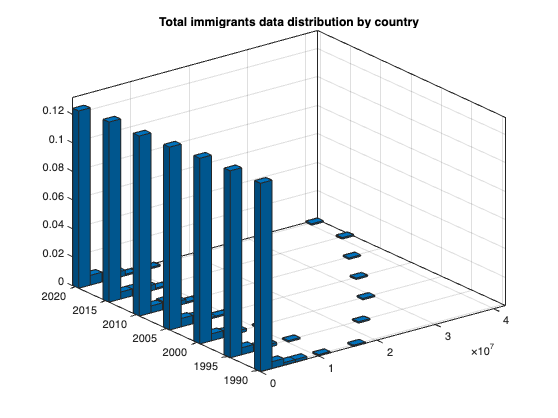

histogram2(migrationT.Total_Immigrants, migrationT.Year, "Normalization", "probability")
title("Total immigrants data distribution by country")

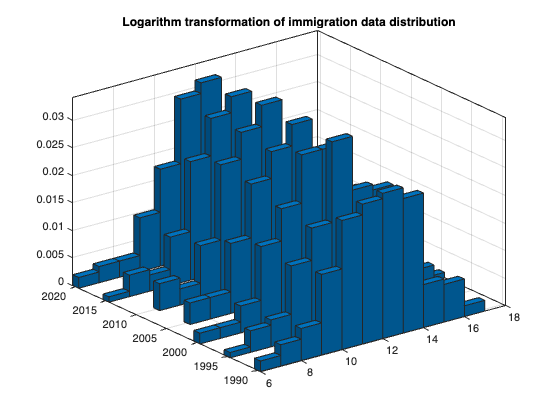

histogram2(log(migrationT.Total_Immigrants+1), migrationT.Year, "Normalization", "probability")
title("Logarithm transformation of immigration data distribution")

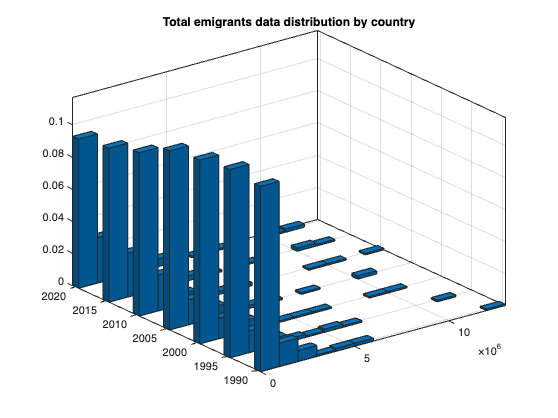


histogram2(abs(migrationT.Total_Emigrants), migrationT.Year, "Normalization", "probability")
title("Total emigrants data distribution by country")

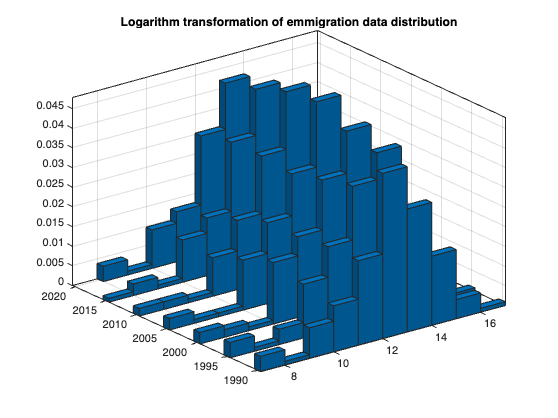

histogram2(log(abs(migrationT.Total_Emigrants)+1), migrationT.Year, "Normalization", "probability")
title("Logarithm transformation of emmigration data distribution")

## Economy Indicator Table

T1 = outerjoin(giniT, humanDvpmT,'Keys', {'Country', 'Code', 'Year'}, 'MergeKeys', true);
T2 = outerjoin(T1, unemploymentT,'Keys', {'Country', 'Code', 'Year'}, 'MergeKeys', true);
economyT = outerjoin(T2, gdpT,'Keys', {'Country', 'Code', 'Year'}, 'MergeKeys', true);

head(economyT)

     Country     Code     Year    Gini_coeff    Human_Dvpm_Index    Unemployment_Rate    GDP_per_capita    Population    Continent
    _________    _____    ____    __________    ________________    _________________    ______________    __________    _________

    "Albania"    "ALB"    1990     0.22282           0.649               7.2149              4827.1         3.278e+06    "Europe" 
    "Albania"    "ALB"    1995     0.26222           0.632               14.611              4471.6        3.2586e+06    "Europe" 
    "Albania"    "ALB"    2000     0.30163           0.678               19.028              5892.6        3.1661e+06    "Europe" 
    "Albania"    "ALB"    2005     0.3

summary(economyT)

Variables:

    Country: 1022×1 string

        Properties:
            Units:  categorical
    Code: 1022×1 string

        Properties:
            Units:  categorical
    Year: 1022×1 double

        Properties:
            Units:  int
        Values:

            Min         1990  
            Median      2005  
            Max         2020  

    Gini_coeff: 1022×1 double

        Properties:
            Units:  double
        Values:

            Min       0.14492 
            Median    0.37882 
            Max       0.85481 

    Human_Dvpm_Index: 1022×1 double

        Properties:
            Units:  double
        Values:

            Min        0.2002 
            Median      0.658 
            Max         0.963 

    Unemployment_Rate: 1022×1 double

        Properties:
            Units:  double
        Values:

            Min         0.42  
            Median     6.452  
 


clearvars("T1", "T2")

## Save Tables

#### Save migration table

if ~isfile("./Tables/migrationT.mat")
    % Save migration table
    save("./Tables/migrationT.mat", "migrationT")
else
    T = load("./Tables/migrationT.mat");
    T = T.migrationT;        
    if size(T, 1)~=size(migrationT, 1) | size(T, 2)~=size(migrationT, 2) | any(T{:, :}~=migrationT{:, :}, "all")
        % Save migration table only if changes were applied
        save("./Tables/migrationT.mat", "migrationT")
    end
end

clearvars("T")

#### Save GDP per capita table

if ~isfile("./Tables/gdpT.mat")
    % Save gdpT table
    save("./Tables/gdpT", "gdpT")
else
    T = load("./Tables/gdpT.mat");
    T = T.gdpT;        
    if size(T, 1)~=size(gdpT, 1) | size(T, 2)~=size(gdpT, 2) | any(T{:, :}~=gdpT{:, :}, "all")
        % Save gdpT table only if changes were applied
        save("./Tables/gdpT.mat", "gdpT")
    end
end

clearvars("T")

#### Save Gini coefficient table

if ~isfile("./Tables/giniT.mat")
    % Save giniT table
    save("./Tables/giniT", "giniT")
else
    T = load("./Tables/giniT.mat");
    T = T.giniT;        
    if size(T, 1)~=size(giniT, 1) | size(T, 2)~=size(giniT, 2) | any(T{:, :}~=giniT{:, :}, "all")
        % Save giniT table only if changes were applied
        save("./Tables/giniT.mat", "giniT")
    end
end

clearvars("T")

#### Save Human-Development Index table

if ~isfile("./Tables/humanDvpmT.mat")
    % Save humanDvpmT table
    save("./Tables/humanDvpmT", "humanDvpmT")
else
    T = load("./Tables/humanDvpmT.mat");
    T = T.humanDvpmT;        
    if size(T, 1)~=size(humanDvpmT, 1) | size(T, 2)~=size(humanDvpmT, 2) | any(T{:, :}~=humanDvpmT{:, :}, "all")
        % Save humanDvpmT table only if changes were applied
        save("./Tables/humanDvpmT.mat", "humanDvpmT")
    end
end

clearvars("T")

#### Save Unemployment Rate table

if ~isfile("./Tables/unemploymentT.mat")
    % Save unemploymentT table
    save("./Tables/unemploymentT", "unemploymentT")
else
    T = load("./Tables/unemploymentT.mat");
    T = T.unemploymentT;        
    if size(T, 1)~=size(unemploymentT, 1) | size(T, 2)~=size(unemploymentT, 2) | any(T{:, :}~=unemploymentT{:, :}, "all")
        % Save unemploymentT table only if changes were applied
        save("./Tables/unemploymentT.mat", "unemploymentT")
    end
end

clearvars("T")

#### Save Economy Indicator table

if ~isfile("./Tables/economyT.mat")
    % Save economyT table
    save("./Tables/economyT", "economyT")
else
    T = load("./Tables/economyT.mat");
    T = T.economyT;        
    if size(T, 1)~=size(economyT, 1) | size(T, 2)~=size(economyT, 2) | any(T{:, :}~=economyT{:, :}, "all")
        % Save economyT table only if changes were applied
        save("./Tables/economyT.mat", "economyT")
    end
end

clearvars("T")

#### Save Distance table

if ~isfile("./Tables/distanceT.mat")
    % Save distanceT table
    save("./Tables/distanceT", "distanceT")
else
    T = load("./Tables/distanceT.mat");
    T = T.distanceT;        
    if size(T, 1)~=size(distanceT, 1) | size(T, 2)~=size(distanceT, 2) | any(T{:, :}~=distanceT{:, :}, "all")
        % Save distanceT table only if changes were applied
        save("./Tables/distanceT.mat", "distanceT")
    end
end

clearvars("T")